# **PESTools - Example 005 - Showcase of the available PES model curves that can be used for fitting**

## Author : PCC

This example shows all of the curve line-shapes that are available to use when fitting to either ARPES or XPS data obtained from the ADRESS beamline. 

- **For PES curves:** **Gaussian**, **Lorentzian**, **Voigt**, **asymmetrical Voigt **and **Doniach-Sunjic** functions are all available.

- The **Fermi-Dirac Distribution** **(FDD)** is also defined here, which can be also used for fitting states near the Fermi-edge.

close all; clear all;
pp = plot_props();

# **The functions below are used to create a general best-fit lineshape to PES data**

**(1) Generic, vanilla PES curve**

The function 'PESCurve()' can be used to call any curve line-shape that can be used to fit to PES data.  The option is here to also plot its spin-orbit split component, along with its energy shift and branching ratio. Using a linear combination of 'PESCurve()' outputs, we can then fit to any PES data.

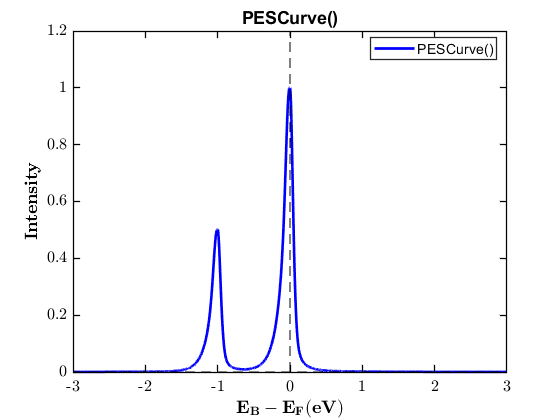

% 1 - Defining the input parameters
xdat = linspace(-3, 3, 1e4);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  0.0;      % scalar of the binding energy of PE curve.
INT     =  1.0;      % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.1;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
% 2 - Calculating the lineshape
zdat    = PESCurve(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY);
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); plot(xdat, zdat, 'b-', 'linewidth', 2);
gca_props(); title('PESCurve()', 'Interpreter','none'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
legend({'PESCurve()'}, 'location', 'best', 'Interpreter','none');

**(2) PES curve convolved with a Fermi-Dirac Distribution (FDD) for near Fermi-edge fitting problems**

The function 'PESCurve_FDD()' can be used to call a generic curve line-shape that has been convolved with an FDD. This is useful for near Fermi-edge fitting problems.

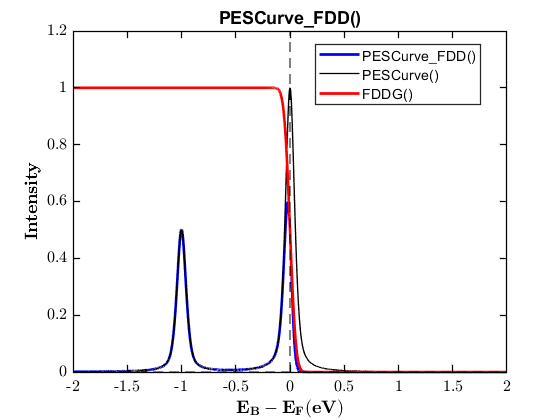

% 1 - Defining the input parameters
xdat = linspace(-2, 2, 1e4);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  0.0;     % scalar of the binding energy of PE curve.
INT     =  1.0;     % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.0;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
FDEF    =  0.0;     % scalar of the FDD Fermi-Level position.
FDT     =  12.0;    % scalar of the FDD temperature.
FDW     =  0.10;    % scalar of the FDD Gaussian width after convolution.
% 2 - Calculating the lineshape
zdat_00     = PESCurve(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY);
zdat_01     = PESCurve_FDD(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, FDEF, FDT, FDW);
zdat_fdd    = FDDG(xdat, FDEF, FDT, FDW);
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on;
plot(xdat, zdat_01, 'b-', 'linewidth', 2);
plot(xdat, zdat_00, 'k-', 'linewidth', 1);
plot(xdat, zdat_fdd, 'r-', 'linewidth', 2);
gca_props(); title('PESCurve_FDD()', 'Interpreter','none');
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
legend({'PESCurve_FDD()', 'PESCurve()', 'FDDG()'}, 'location', 'best', 'Interpreter','none');

**(3) PES curve integrated over a pre-defined/theoretical potential profile**

The function 'PESCurve_POT()' can be used to call any curve line-shape, which takes into account the local potential profile near the surface. The final PES curve here is a linear combination of curves that are offset by the potential energy distribution, scaled in accordance to the exponential decay based on the mean free path (MFP) of the emitted photoelectrons.

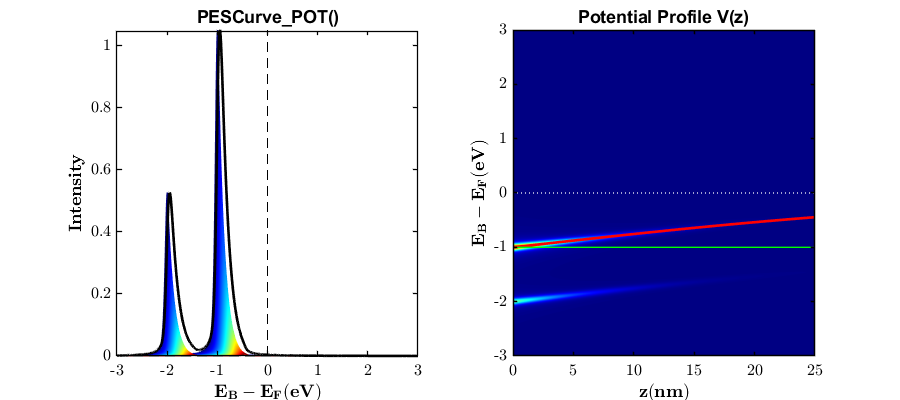

% 1 - Defining the input parameters
xdat = linspace(-3.0, 3.0, 5e3);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  -1.0;    % scalar of the binding energy of PE curve.
INT     =  1.05;    % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % scalar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.0;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
MFP     =  5.0;     % scalar of the mean-free path of the emitted photoelectrons (either from optical, TPP-2M or fits) [nm]
ZPOT    = linspace(0, 25, 400);                           % 1xN array of the z-domain (depth) of the potential profile [eV]
EPOT    = 1.0*(1./(1 + exp(-ZPOT*0.05)) - 0.5) / 0.5;      % 1xN array of the potential energy relative to the Fermi-level [eV]
% 2 - Calculating the lineshape
[zdat, PES_int]     = PESCurve_POT(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, MFP, ZPOT, EPOT);
% 3 - Plotting the final lineshape
% -- Initialising the figure
fig = figure(); set(fig, 'position', [10, 10, 900, 400]);
cols = jet(length(ZPOT)+2);
% -- Plotting all individual curves, shifted by the potential and the final sum
subplot(121); hold on;
% --- Plotting individual curves
for i = 1:length(ZPOT)
    plot(xdat, PES_int(:,i), 'k-', 'color', cols(i,:), 'linewidth', 0.5);
end
% --- Plotting the final curve
plot(xdat, zdat, 'k-', 'linewidth', 2);
% --- Formatting the figure
gca_props(); title('PESCurve_POT()', 'Interpreter','none');
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
axis([min(xdat(:)), max(xdat(:)), 0, max(zdat(:))]);
% -- Plotting the potential profile information
subplot(122); hold on;
% --- Image of the curve series shifted by potential and scaled by MFP
ImData(ZPOT, xdat, PES_int);
% --- Plotting the potential energy curves
plot(ZPOT, EPOT+BE, 'r-', 'linewidth', 2);
plot(ZPOT, BE*ones(size(ZPOT)), 'g-', 'linewidth', 1);
% --- Formatting the figure
img_props(); colormap jet; title('Potential Profile V(z)', 'Interpreter','none');
xlabel('$$ \bf  z (nm) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
axis([0, max(ZPOT(:)), min(xdat(:)), max(xdat(:))]);

# **Symmetric Curves**

xdat = linspace(-3, 3, 1e4);

## (1) Gaussian Lineshape

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
peak        = 1.38;            % scalar of the peak beneath the Gaussian.
fwhm        = 0.5:0.1:1;    % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_gauss{i}    = Gauss(xdat, x0, peak, fwhm(i));
    lgnd{i}         = "GauW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(fwhm) + 1);
for i = 1:length(fwhm)
    plot(xdat, int_gauss{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_gauss{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_gauss{i}(:));                      % Find the half max value
    index1  = find(int_gauss{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_gauss{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                  % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.50, peak = 1.38"

ans = "FWHM = 0.60, peak = 1.38"

ans = "FWHM = 0.70, peak = 1.38"

ans = "FWHM = 0.80, peak = 1.38"

ans = "FWHM = 0.90, peak = 1.38"

ans = "FWHM = 1.00, peak = 1.38"

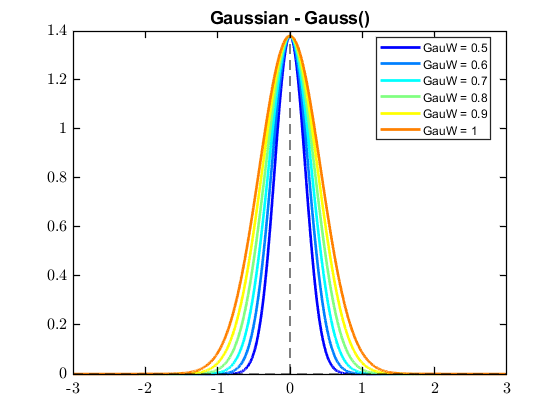

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian - Gauss()');

## (2) Lorentzian Lineshape

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 0.93;            % scalar of the peak beneath the Lorentzian.
fwhm        = 0.5:0.1:1;    % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_lorentz{i}    = Lorentzian(xdat, x0, peak, fwhm(i));
    lgnd{i}           = "LorW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(fwhm) + 1);
for i = 1:length(fwhm)
    plot(xdat, int_lorentz{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_lorentz{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_lorentz{i}(:));                      % Find the half max value
    index1  = find(int_lorentz{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_lorentz{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                     % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.50, peak = 0.93"

ans = "FWHM = 0.60, peak = 0.93"

ans = "FWHM = 0.70, peak = 0.93"

ans = "FWHM = 0.80, peak = 0.93"

ans = "FWHM = 0.90, peak = 0.93"

ans = "FWHM = 1.00, peak = 0.93"

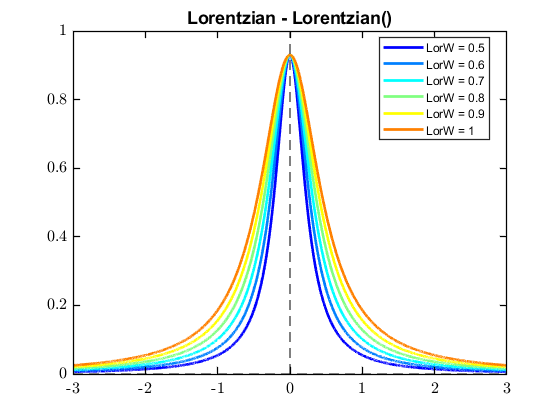

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Lorentzian - Lorentzian()');

## (3) Pseudo-Voigt Lineshape - Gaussian / Lorentzian Sum

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.0;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.75;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.1:0.1:1;    % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(mr)
    int_sGL{i}    = sGL(xdat, x0, peak, fwhm, mr(i));
    lgnd{i}         = "sGL-MR = " + string(mr(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(mr) + 1);
for i = 1:length(mr)
    plot(xdat, int_sGL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_sGL{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_sGL{i}(:));                      % Find the half max value
    index1  = find(int_sGL{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_sGL{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                   % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

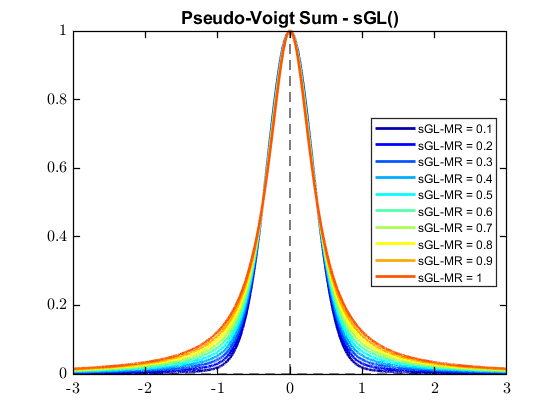

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Pseudo-Voigt Sum - sGL()');

## (4) Pseudo-Voigt Lineshape - Gaussian / Lorentzian Product

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.0;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.75;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.1:0.1:1;    % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(mr)
    int_pGL{i}    = pGL(xdat, x0, peak, fwhm, mr(i));
    lgnd{i}       = "pGL-MR = " + string(mr(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(mr) + 1);
for i = 1:length(mr)
    plot(xdat, int_pGL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_pGL{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_pGL{i}(:));                      % Find the half max value
    index1  = find(int_pGL{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_pGL{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                   % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.74, peak = 1.00"

ans = "FWHM = 0.73, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.73, peak = 1.00"

ans = "FWHM = 0.74, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

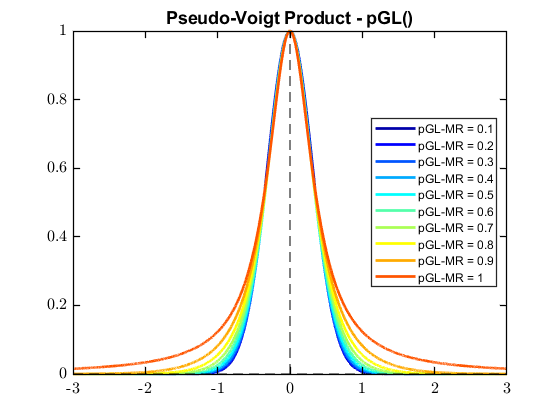

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Pseudo-Voigt Product - pGL()');

# **Asymmetric Curves**

xdat = linspace(-3, 3, 1e4);

## (1) Doniach-Sunjic Lineshape

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.0;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.15;         % scalar of the width parameter
asym        = 0.0:0.05:0.50;    % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(asym)
    int_DS{i}    = DoniachSunjic(xdat, x0, peak, fwhm, asym(i));
    lgnd{i}         = "DS-asym = " + string(asym(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(asym) + 1);
for i = 1:length(asym)
    plot(xdat, int_DS{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_DS{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_DS{i}(:));                      % Find the half max value
    index1  = find(int_DS{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_DS{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                   % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.30, peak = 1.00"

ans = "FWHM = 0.32, peak = 1.00"

ans = "FWHM = 0.34, peak = 1.00"

ans = "FWHM = 0.37, peak = 1.00"

ans = "FWHM = 0.40, peak = 1.00"

ans = "FWHM = 0.45, peak = 1.00"

ans = "FWHM = 0.50, peak = 1.00"

ans = "FWHM = 0.58, peak = 1.00"

ans = "FWHM = 0.68, peak = 1.00"

ans = "FWHM = 0.81, peak = 1.00"

ans = "FWHM = 1.02, peak = 1.00"

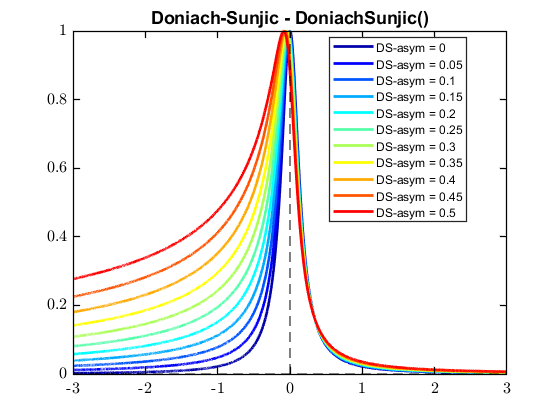

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Doniach-Sunjic - DoniachSunjic()');

## (2) Asymmetric Pseudo-Voigt Lineshape - Gaussian / Lorentzian Sum

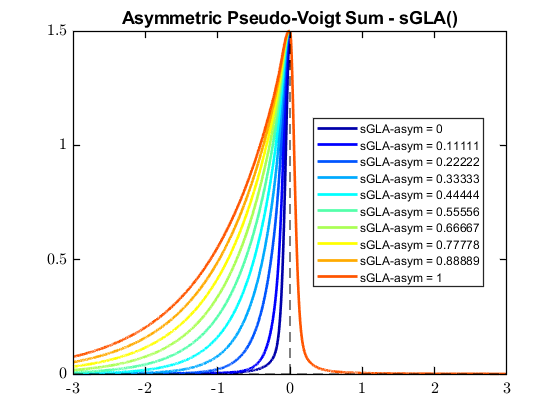

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.5;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.15;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.5;          % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
asym        = linspace(0,1,10);            % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(asym)
    int_sGLA{i}    = sGLA(xdat, x0, peak, fwhm, mr, asym(i));
    lgnd{i}        = "sGLA-asym = " + string(asym(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(asym) + 1);
for i = 1:length(asym)
    plot(xdat, int_sGLA{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Asymmetric Pseudo-Voigt Sum - sGLA()');

## (3) Asymmetric Pseudo-Voigt Lineshape - Gaussian / Lorentzian Product

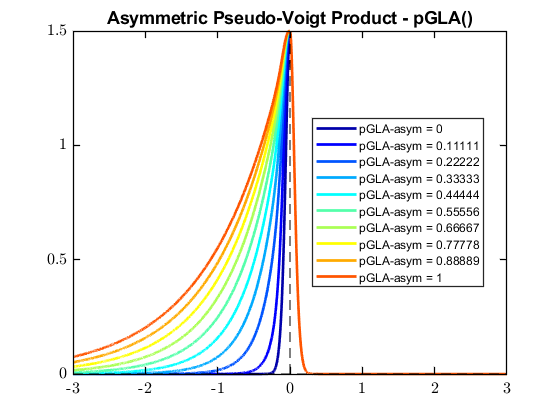

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.5;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.15;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.5;          % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
asym        = linspace(0,1,10);            % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(asym)
    int_pGLA{i}    = pGLA(xdat, x0, peak, fwhm, mr, asym(i));
    lgnd{i}        = "pGLA-asym = " + string(asym(i));
    % -- Extracting the exponential blend function
    int_AEB{i}      = AEB(xdat, x0, asym(i));
    int_AEB{i}      = int_AEB{i} .* (max(int_pGLA{i}(:)) - int_pGLA{i});
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(asym) + 1);
for i = 1:length(asym)
    plot(xdat, int_pGLA{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
%     h = plot(xdat, int_AEB{i}, 'k--', 'color', col_gauss(i,:), 'linewidth', 1);
%     h.Annotation.LegendInformation.IconDisplayStyle = 'off';
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Asymmetric Pseudo-Voigt Product - pGLA()');

## (4) Asymmetric Pseudo-Voigt Lineshape - Gaussian / Lorentzian Product - Convolved with FDD function

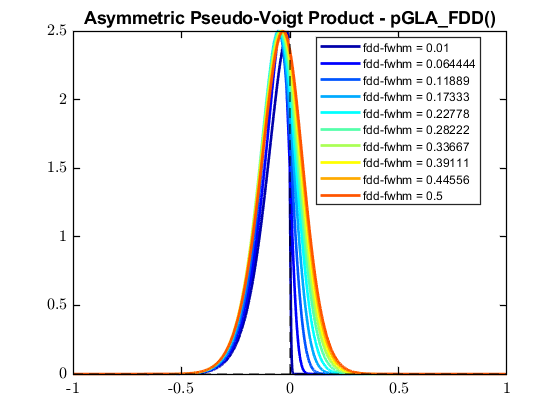

xdat = linspace(-1, 1, 1e4);
% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 2.50;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.25;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.5;          % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
asym        = 0.0;          % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
fdd_ef      = 0.0;            % scalar of the location of the Fermi-level
fdd_T       = 12;           % scalar of the temperature of the system
fdd_fwhm    = linspace(0.01, 0.5, 10);         % scalar of the Gaussian FWHM to be convolved

% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(fdd_fwhm)
    int_pGLA_FDD{i}     = pGLA_FDD(xdat, x0, peak, fwhm, mr, asym, fdd_ef, fdd_T, fdd_fwhm(i));
    lgnd{i}             = "fdd-fwhm = " + string(fdd_fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(fdd_fwhm) + 1);
for i = 1:length(fdd_fwhm)
    plot(xdat, int_pGLA_FDD{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Asymmetric Pseudo-Voigt Product - pGLA_FDD()', 'interpreter', 'none');

# **Fermi-Dirac Distributions**

xdat = linspace(-1, 1, 1e4);

## (1) Pure FDD function

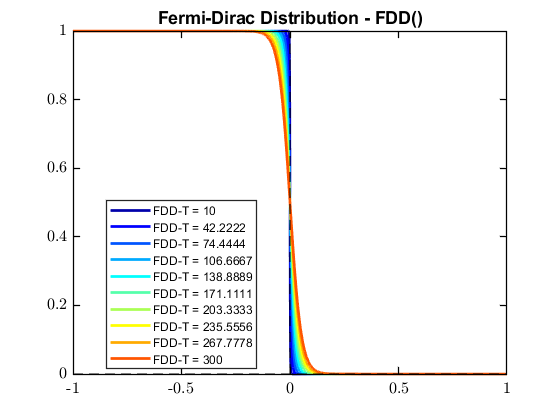

% 1 - Defining the input parameters
FDEF          = 0;                  % scalar of the location of the Fermi-level
FDT        = linspace(10, 300, 10); % scalar of the temperature of the system
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(FDT)
    int_FDD{i}    = FDD(xdat, FDEF, FDT(i));
    lgnd{i}       = "FDD-T = " + string(FDT(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(FDT) + 1);
for i = 1:length(FDT)
    plot(xdat, int_FDD{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Fermi-Dirac Distribution - FDD()');

## (2) Gaussian broadened FDD function

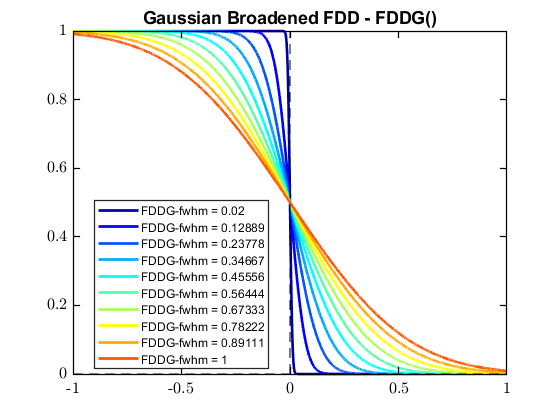

% 1 - Defining the input parameters
FDEF        = 0;            % scalar of the location of the Fermi-level
FDT         = 12;           % scalar of the temperature of the system
FDW         = linspace(0.02, 1.0, 10);         % scalar of the Gaussian FWHM to be convolved
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(FDW)
    int_FDDG{i}    = FDDG(xdat, FDEF, FDT, FDW(i));
    lgnd{i}       = "FDDG-fwhm = " + string(FDW(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(FDW) + 1);
for i = 1:length(FDW)
    plot(xdat, int_FDDG{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian Broadened FDD - FDDG()');

## (3) Gaussian broadened FDD function with a linear background multiplied

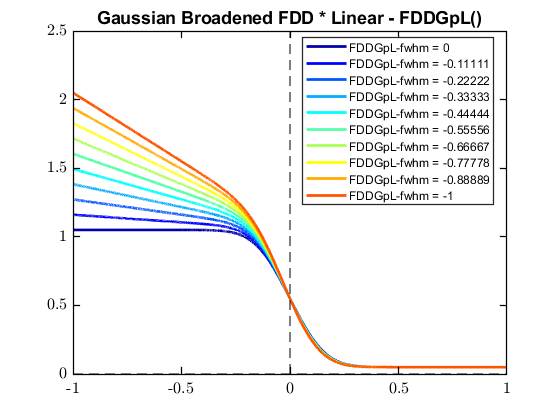

% 1 - Defining the input parameters
FDEF    = 0.0;          % scalar of the location of the Fermi-level
FDT     = 12;           % scalar of the temperature of the system
FDW     = 0.30;         % scalar of the Gaussian FWHM to be convolved
BGR     = -linspace(0, 1, 10);% scalar of the gradient of the linear background.
BIN     = 1.;           % scalar of the y-intercept of the linear background.
BCO     = 0.05;         % scalar of the constant background y-offset value.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(BGR)
    int_FDDGpL{i}    = FDDGpL(xdat, FDEF, FDT, FDW, BGR(i), BIN, BCO);
    lgnd{i}       = "FDDGpL-fwhm = " + string(BGR(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(BGR) + 1);
for i = 1:length(BGR)
    plot(xdat, int_FDDGpL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian Broadened FDD * Linear - FDDGpL()');

## (4) Gaussian broadened FDD function with a linear background added

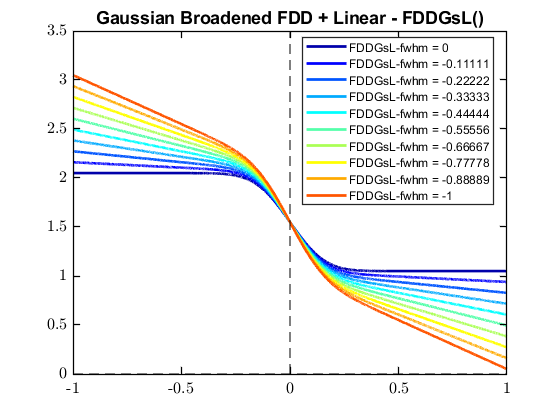

% 1 - Defining the input parameters
FDEF      = 0.0;            % scalar of the location of the Fermi-level
FDT    = 12;           % scalar of the temperature of the system
FDW   = 0.30;         % scalar of the Gaussian FWHM to be convolved
BGR    = -linspace(0, 1, 10);
BIN    = 1.;
BCO   = 0.05;
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(BGR)
    int_FDDGsL{i}    = FDDGsL(xdat, FDEF, FDT, FDW, BGR(i), BIN, BCO);
    lgnd{i}       = "FDDGsL-fwhm = " + string(BGR(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(BGR) + 1);
for i = 1:length(BGR)
    plot(xdat, int_FDDGsL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian Broadened FDD + Linear - FDDGsL()');

# **APPENDIX : A LIST OF USEFUL MISCELLANEOUS FUNCTIONS**

## Appendix I - Extracting the peak position of a curve

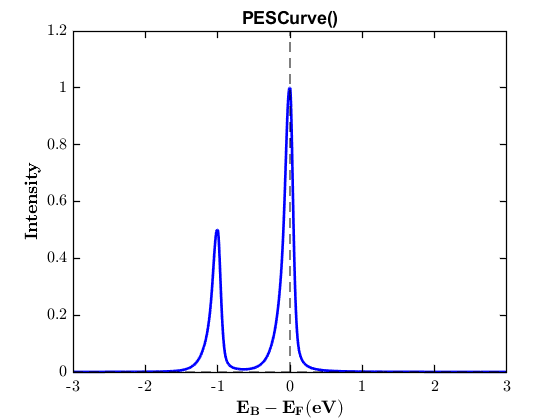

% 1 - Defining a curve to be used
xdat = linspace(-3, 3, 1e3);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      = 0.0;      % scalar of the binding energy of PE curve.
INT     = 1.0;      % scalar of the peak intensity of PE curve.
FDW    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.1;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
% 2 - Calculating the lineshape
zdat    = PESCurve(xdat, TYPE, BE, INT, FDW, MR, LSE, LSI, LSW, ASY);
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); plot(xdat, zdat, 'b-', 'linewidth', 2);
gca_props(); title('PESCurve()'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');

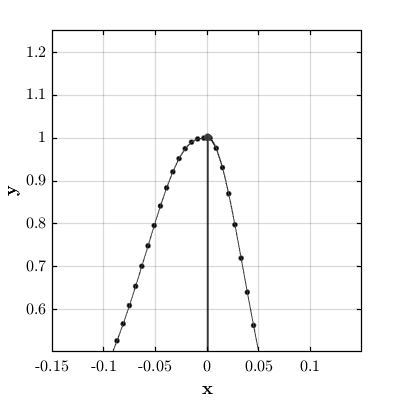

1) x = 0.00 eV, y = 1.00 


% 4 - Finding the peak position of the curve
[xval, yval] = find_peak_loc(xdat, zdat, [-0.15, 0.15], "spline");